## Histogram Equalization

- Read teh image and convert the image to a grayscale image

imc = imread('im2.png');% Read the image
img = rgb2gray(imc); % Convert to grayscale
imshow(img); % View image

  2. Grayscale images have 256 gray levels. Therefore create an empty matrix having dimensions of 1 × 256 and generate the histogram.

H=size(img,1); % Read the height of the image
W=size(img,2); % Read the width of the image
Hist_arr=zeros(1,256); % Array for holding the (original) histogram
Hist_eq_arr=zeros(1,256); % Array for holding the (equalized) histogram
CDF_array=zeros(1,length(Hist_arr)); % array to hold cumulative distribution function (CDF)
hist_eq_img=uint8(zeros(H,W)); % A 2D array for keeping histogram equalized image (intensity in 8 bit integers)
for i=1:H
    for j=1:W
    Hist_arr(1,img(i,j)+1)=Hist_arr (1,img(i,j)+1)+1;
    end
end

3. Calculate $p_r(r_k)$  for the image. (Total number of pixels = ymax × xmax)

Hist_arr_pdf=Hist_arr/(H*W); % PDF

4. Calculate the CDF from the PDF

dummy1=0; % A dummy variable to hold the summation results
for k=1:length(Hist_arr) % Generating the CDF from PDF
    dummy1=dummy1+Hist_arr_pdf(k);
    CDF_array(k)= dummy1;
end

5. Calculate the equalized histogram using equation 1 and map the original gray levels to the new gray levels.

for l=1:H % Histogram equalization
    for m=1:W
    hist_eq_img(l,m)= round(CDF_array(img(l,m)+1)*...
        (length(Hist_arr_pdf)-1)); % scale to 255 and round to nearest integer
    Hist_eq_arr(1, hist_eq_img(l,m)+1)=...
        Hist_eq_arr (1,hist_eq_img(l,m)+1)+1 ;% Its histogram
    end
end

6. Display both images, before and after histogram equalization.

    Display both histograms.

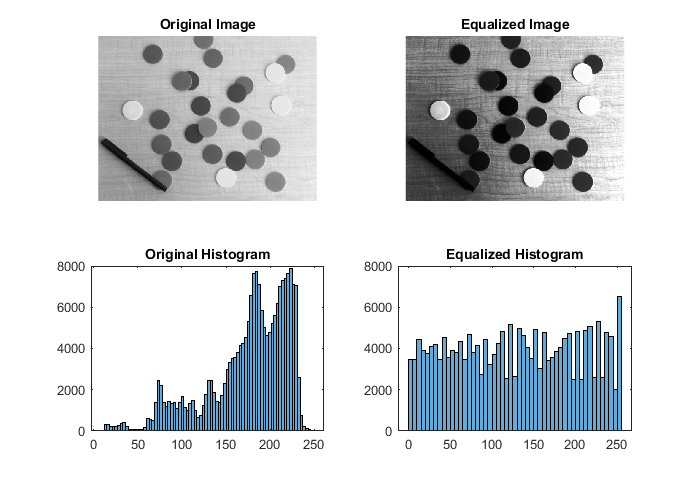

subplot(2,2,1)
imshow(img)
title("Original Image")
subplot(2,2,2)
imshow(hist_eq_img)
title("Equalized Image")
subplot(2,2,3)
histogram(img)
title("Original Histogram")
subplot(2,2,4)
histogram(hist_eq_img)
title("Equalized Histogram")